# Próbkowanie sygnałów analogowych

A)

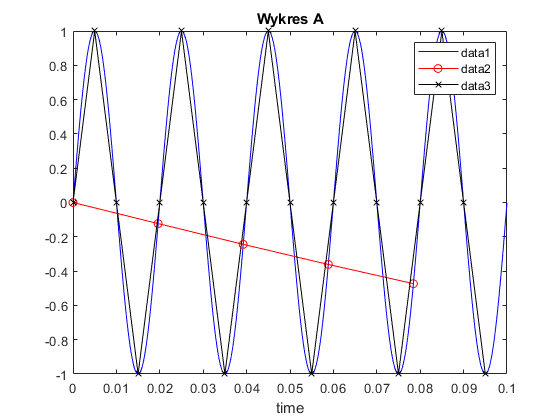

init1.fs = 50;
init1.end_time = 0.1;
init1.a = 230;

gen1.f10kHz =  arrayfun(@(p) sin(2*p*pi*init1.fs), [0:0.00001:init1.end_time-0.00001]);
gen1.f51Hz = arrayfun(@(p) sin(2*p*pi*init1.fs), [0:1/51:init1.end_time-1/51]);
gen1.f200Hz = arrayfun(@(p) sin(2*p*pi*init1.fs), [0:0.005:init1.end_time-0.005]);

clf
figure(1)
plot([0:0.00001:init1.end_time-0.00001],gen1.f10kHz, 'b-')
hold on
plot([0:1/51:init1.end_time-1/51],gen1.f51Hz,'r-o')
plot([0:0.005:init1.end_time-0.005],gen1.f200Hz,'k-x')
set(gca,'XLim', [0,0.1])

legend('show')
xlabel('time')

title('Wykres A')

B)

disp("B:")

B:


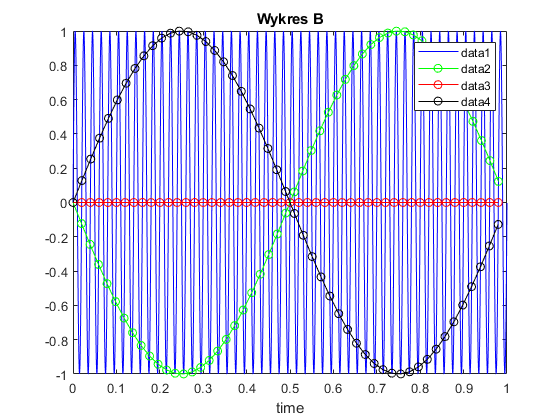

init2.fs = 50;
init2.end_time = 1;

gen2.f10kHz =  arrayfun(@(p) sin(2*p*pi*init2.fs), [0:0.00001:init2.end_time-0.00001]);
gen2.f51Hz = arrayfun(@(p) sin(2*p*pi*init2.fs), [0:1/51:init2.end_time-1/51]);
gen2.f50Hz = arrayfun(@(p) sin(2*p*pi*init2.fs), [0:0.02:init2.end_time-0.02]);
gen2.f49Hz = arrayfun(@(p) sin(2*p*pi*init2.fs), [0:1/49:init2.end_time-1/49]);

clf
figure(2)
plot([0:0.00001:init2.end_time-0.00001], gen2.f10kHz, 'b-')
hold on
plot([0:1/51:init2.end_time-1/51], gen2.f51Hz, 'g-o')
plot([0:0.02:init2.end_time-0.02], gen2.f50Hz, 'r-o')
plot([0:1/49:init2.end_time-1/49], gen2.f49Hz, 'k-o')

legend('show')
xlabel('time')

title('Wykres B')

C)

disp("C:")

C:


gen3 = f_generate(@(x) sin(2*pi*x*[0:1/100:1-1/100]), [], 0, 300);

    "num: 1, freq: 0"

    "num: 2, freq: 5"

    "num: 3, freq: 10"

    "num: 4, freq: 15"

    "num: 5, freq: 20"

    "num: 6, freq: 25"

    "num: 7, freq: 30"

    "num: 8, freq: 35"

    "num: 9, freq: 40"

    "num: 10, freq: 45"

    "num: 11, freq: 50"

    "num: 12, freq: 55"

    "num: 13, freq: 60"

    "num: 14, freq: 65"

    "num: 15, freq: 70"

    "num: 16, freq: 75"

    "num: 17, freq: 80"

    "num: 18, freq: 85"

    "num: 19, freq: 90"

    "num: 20, freq: 95"

    "num: 21, freq: 100"

    "num: 22, freq: 105"

    "num: 23, freq: 110"

    "num: 24, freq: 115"

    "num: 25, freq: 120"

    "num: 26, freq: 125"

    "num: 27, freq: 130"

    "num: 28, freq: 135"

    "num: 29, freq: 140"

    "num: 30, freq: 145"

    "num: 31, freq: 150"

    "num: 32, freq: 155"

    "num: 33, freq: 160"

    "num: 34, freq: 165"

    "num: 35, freq: 170"

    "num: 36, freq: 175"

    "num: 37, freq: 180"

    "num: 38, freq: 185"

    "num: 39, freq: 190"

    "num: 40, fre

gen4 = f_generate(@(x) cos(2*pi*x*[0:1/100:1-1/100]), [], 0, 300);

    "num: 1, freq: 0"

    "num: 2, freq: 5"

    "num: 3, freq: 10"

    "num: 4, freq: 15"

    "num: 5, freq: 20"

    "num: 6, freq: 25"

    "num: 7, freq: 30"

    "num: 8, freq: 35"

    "num: 9, freq: 40"

    "num: 10, freq: 45"

    "num: 11, freq: 50"

    "num: 12, freq: 55"

    "num: 13, freq: 60"

    "num: 14, freq: 65"

    "num: 15, freq: 70"

    "num: 16, freq: 75"

    "num: 17, freq: 80"

    "num: 18, freq: 85"

    "num: 19, freq: 90"

    "num: 20, freq: 95"

    "num: 21, freq: 100"

    "num: 22, freq: 105"

    "num: 23, freq: 110"

    "num: 24, freq: 115"

    "num: 25, freq: 120"

    "num: 26, freq: 125"

    "num: 27, freq: 130"

    "num: 28, freq: 135"

    "num: 29, freq: 140"

    "num: 30, freq: 145"

    "num: 31, freq: 150"

    "num: 32, freq: 155"

    "num: 33, freq: 160"

    "num: 34, freq: 165"

    "num: 35, freq: 170"

    "num: 36, freq: 175"

    "num: 37, freq: 180"

    "num: 38, freq: 185"

    "num: 39, freq: 190"

    "num: 40, fre

wykresy dla `sin()`

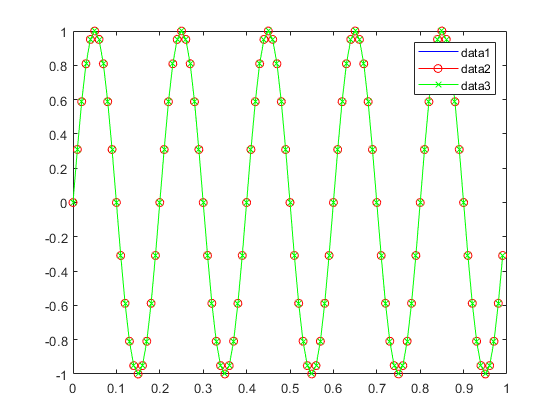

%clf(3)
figure(3)
plot([0:1/100:1-1/100], gen3(2,:), 'b-')
hold on
plot([0:1/100:1-1/100], gen3(22,:), 'r-o')
plot([0:1/100:1-1/100], gen3(42,:), 'g-x')
legend('show')

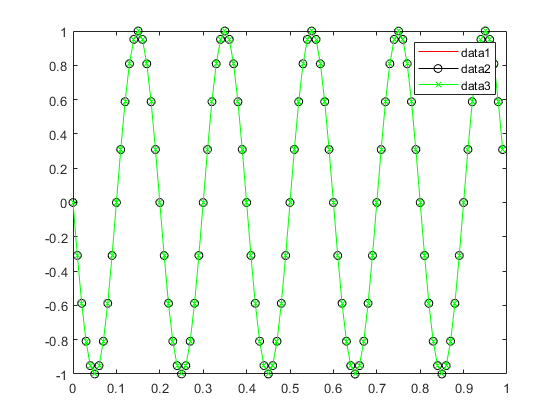


%clf(4)
figure(4)
plot([0:1/100:1-1/100], gen3(20,:), 'r-')
hold on
plot([0:1/100:1-1/100], gen3(40,:), 'k-o')
plot([0:1/100:1-1/100], gen3(60,:), 'g-x')
legend('show')

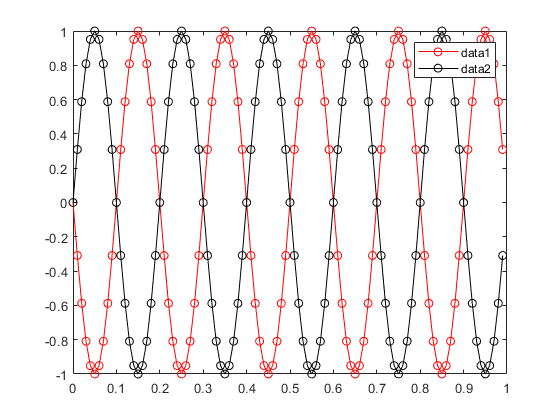


%clf(5)
figure(5)
plot([0:1/100:1-1/100], gen3(20,:), 'r-o')
hold on
plot([0:1/100:1-1/100], gen3(22,:), 'k-o')
legend('show')

wykresy dla `cos()`

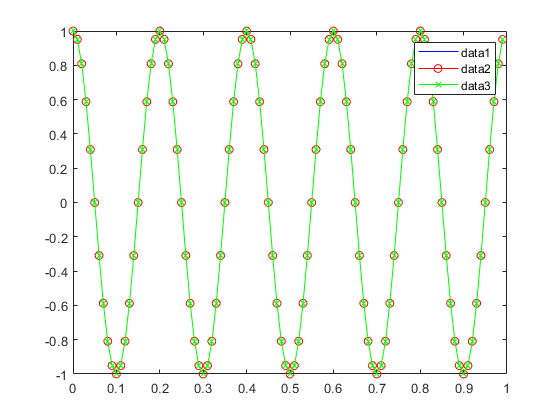

%clf(6)
figure(6)
plot([0:1/100:1-1/100], gen4(2,:), 'b-')
hold on
plot([0:1/100:1-1/100], gen4(22,:), 'r-o')
plot([0:1/100:1-1/100], gen4(42,:), 'g-x')
legend('show')

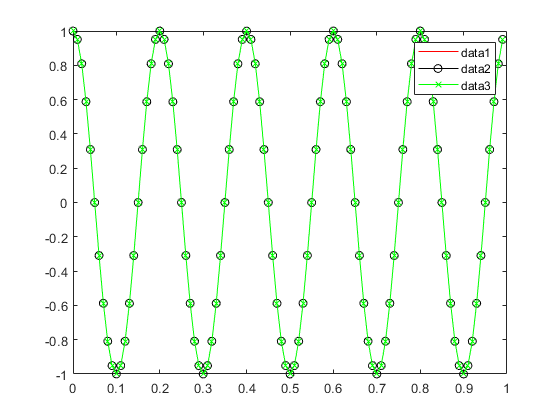


%clf(7)
figure(7)
plot([0:1/100:1-1/100], gen4(20,:), 'r-')
hold on
plot([0:1/100:1-1/100], gen4(40,:), 'k-o')
plot([0:1/100:1-1/100], gen4(60,:), 'g-x')
legend('show')

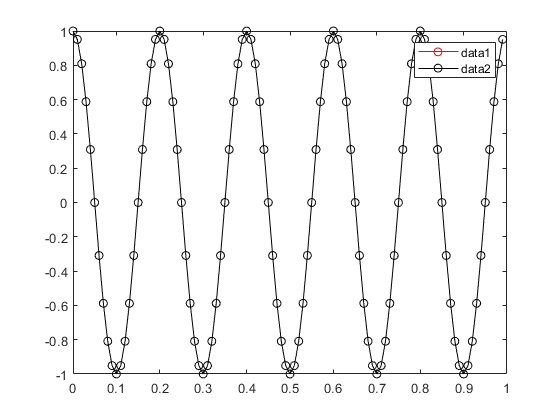


%clf(8)
figure(8)
plot([0:1/100:1-1/100], gen4(20,:), 'r-o')
hold on
plot([0:1/100:1-1/100], gen4(22,:), 'k-o')
legend('show')

D) opcjonalne 

disp("OPCJONALNE")

OPCJONALNE


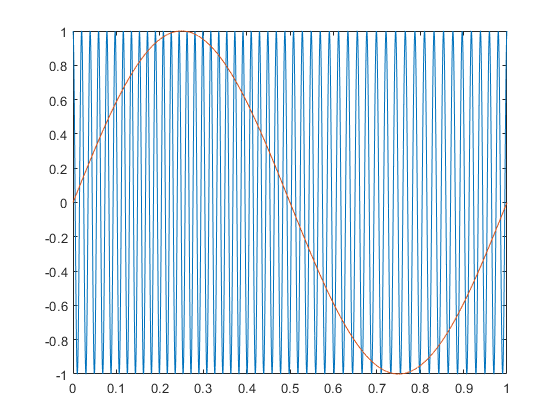

gen_extra(1,:) =  [0:0.0001:1-0.0001];
gen_extra(2,:) = fmmod(sin(2*pi*1*gen_extra(1,:)), 50, 10000, 5);

%clf(10)
figure(10)
plot(gen_extra(1,:),gen_extra(2,:))
hold on
plot(gen_extra(1,:), sin(2*pi*1*gen_extra(1,:)))

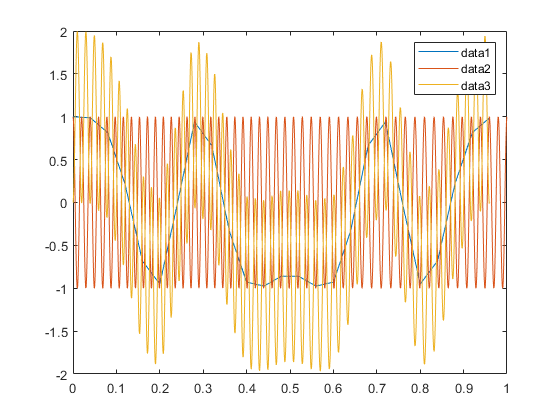



%clf(11)
figure(11)
plot(gen_extra(1,1:400:end),gen_extra(2,1:400:end))
hold on
plot(gen_extra(1,:),gen_extra(2,:))
% blad probkowania 
refined_A = interp1(gen_extra(1,:), gen_extra(2,:), gen_extra(1,:));
refined_B = interp1(gen_extra(1,1:400:end), gen_extra(2,1:400:end), gen_extra(1,:));
plot(gen_extra(1,:), refined_B - refined_A)

legend('show')

function M = f_generate(func, M, fc, end_fc)
    if end_fc+5 == fc
        return;
    end
    display("num: " + (size(M,1)+1) + ", freq: " + fc)
    M(end+1,:) = func(fc);
    M = f_generate(func, M, fc+5, end_fc);
end

function [] = show_plots(gen, plots_to_show, style)
    clf
    figure()
    plot([0:1/100:1-1/100], gen(plots_to_show(1),:), style(1))
    hold on
    for i=2:length(plots_to_show)
        plot([0:1/100:1-1/100], gen(plots_to_show(i),:), style(i))
    end
end

% show_plots(gen3, [2, 22, 42, ...
%                   20, 40, 60, ...
%                   20, 22 ] ...
%                   , ['b-', 'r-o', 'g-x', ...
%                   'b-', 'r-o', 'g-x', ...
%                   'r-o', 'k-o'])